fullM = gdpa_fit('30_50_0');

starting SGML.
initial objective value = -18276.6217
 
converged objective value = -801254.0352
minimal eigenvalue of M = 9.7845e-06
done with SGML.


%fullM = load('../../data/fe_exp/cheng_snap/metric.mat');

% load the data from disc
load('../../data/fe_exp/cheng_snap/data.mat')
train_lbls = train_lbls.';
train_num = size(train_des, 1);

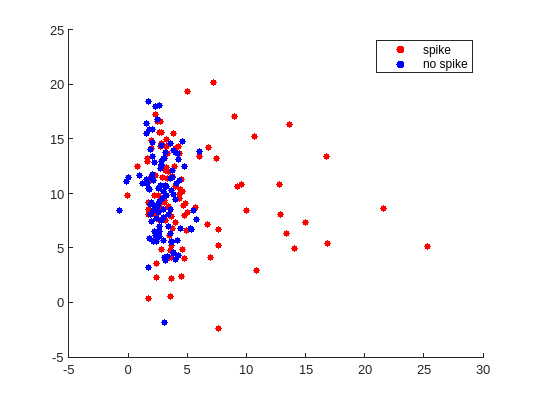

% visualize the dataset
figure;
scatter(train_des(1:floor(train_num/2),1),train_des(1:floor(train_num/2),2),25,'red','filled');
hold on;
scatter(train_des(floor(train_num/2)+1:end,1),train_des(floor(train_num/2)+1:end,2),25,'blue','filled');
legend('spike', 'no spike');
hold off;

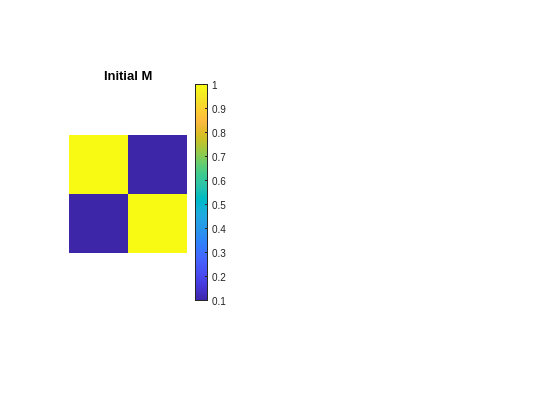

%% visualize the initial metric matrix M0
M0=initial_M(n_feature,2); % initial M as a [1-dense matrix] or [2-sparse matrix]
figure(1);subplot(1,2,1);imagesc(M0);title('Initial M');axis off equal;colorbar; % visual check M0

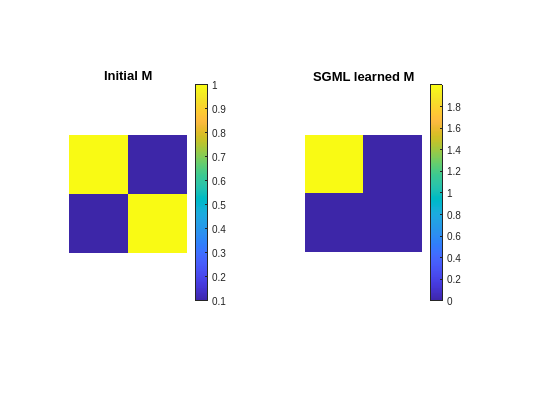

%% visualize the SGML learned metric matrix M
subplot(1,2,2);imagesc(fullM);title('SGML learned M');axis off equal;colorbar; % visual check M